# TP1: Stereovision

### Name: Abdulrahim El Mohamad

### Submitted to: Dr.Abanob Soliman

#### TP Objective : The objective of this exercise is to discover the main challenges facing stereo matching algorithmsWe will start from a very intuitive algorithm and try to suggest avenues for improvement. 

#### *A system of stereo vision system consists of a stereo camera, namely, two cameras placed horizontally (i.e., one on the left and the other on the right). The two images captured simultaneously by these cameras are then processed for the recovery of visual depth information The challenge is to determine the best method of approximating the differences between the views shown in the two images to map (i.e., plot) the correspondence (i.e., disparity) of the environment. Intuitively, a disparity map represents corresponding pixels that are horizontally shifted between the left image and right image. New methods and techniques for solving this problem are developed every year and exhibit a trend toward improvement in accuracy and time consumption.*

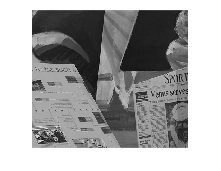

clc; clear all; close all;
%Let us first discover our given images
I1= imread("venus1.ppm");
I2 = imread("venus2.ppm");
I1 = rgb2gray(I1);
I2 = rgb2gray(I2);

imshow(I1)

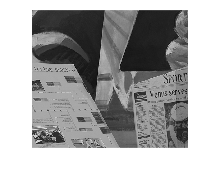

imshow(I2)

We can deduce that the two cameras ar mounted in parallel and to validate this we will use the stereo anaglyph function in matlab that Create red-cyan anaglyph from stereo pair of images

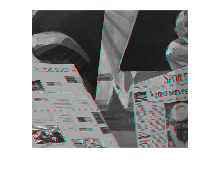

S= stereoAnaglyph(I1,I2);
imshow (S)

Image rectification will  to simplify the problem of finding matching points between images

example: 

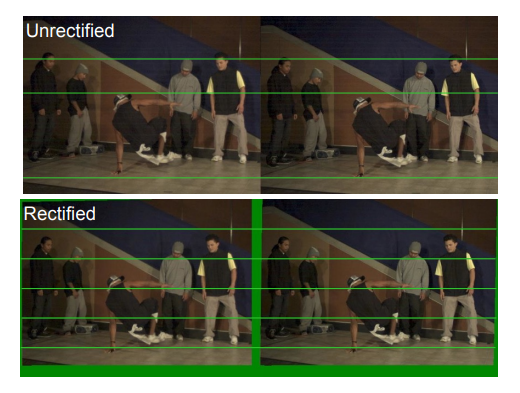

Now we will show the profile for the two images

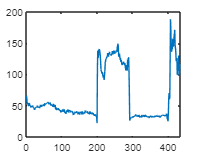

L1 = I1(25,:);
L2 = I2(25,:);

plot(L1)

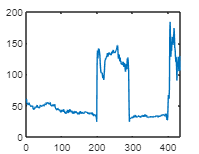

plot(L2)

Minimum and maximum disparity in the image.

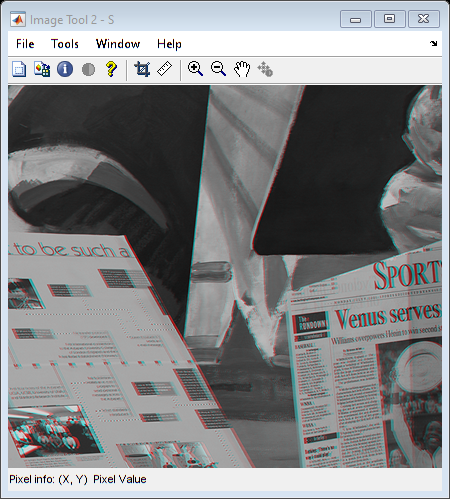

imtool(S,'DisplayRange',[0 255])

clc; clear all; close all;

global D_gt 
D_gt = single(imread('dispGT.pgm'))

D_gt = 383×434 single matrix
    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    31    31    31    31    31    31    31    31    31    31    31    31    31
    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    31    31    31    31    31    31    31    31    31    31    31    31
    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    33    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    31    31    31    31    31    31    31    31    31    31    31    31
    33    33    33    33    33    33    33    33    33    33    33  

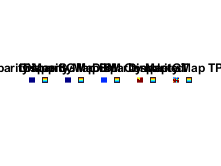


im1 = double(rgb2gray(imread('venus1.ppm')));
im2 = double(rgb2gray(imread('venus2.ppm')));

A = stereoAnaglyph(im1, im2);



disparityRange = [0 48];
disparityMap1 = disparitySGM(im1, im2,'DisparityRange',disparityRange,'UniquenessThreshold',20);
disparityMap2 = disparityBM(im1, im2,'DisparityRange',disparityRange,'UniquenessThreshold',20);

D_TP1 = imdilate(uint8(disparityTP1(im1, im2, 16, 45, 0.01)), offsetstrel('ball',5,5));

% Disparity Map Completion
completed_DMap2 = imdilate(uint8(disparityMap2), offsetstrel('ball',5,5));

figure
subplot(1,5,1)
imshow(disparityMap1,disparityRange)
title('Disparity Map SGM')
colormap jet
colorbar
subplot(1,5,2)
imshow(disparityMap2,disparityRange)
title('Disparity Map BM')
colormap jet
colorbar
subplot(1,5,3)
imshow(completed_DMap2,disparityRange)
title('Disparity Map BM Completed')
colormap jet
colorbar
subplot(1,5,4)
imshow(D_gt,disparityRange)
title('Disparity Map GT')
colormap jet
colorbar

subplot(1,5,5)
imshow(D_TP1,disparityRange)
title('Disparity Map TP')
colormap jet
colorbar

`Larger block size implies smoother, though less accurate disparity map`

The range of disparity must be chosen to cover the minimum and the maximum amount of horizontal shift between the corresponding pixels in the rectified stereo pair image

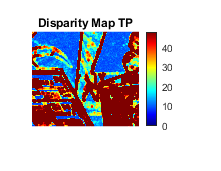

figure
D_TP11 = imdilate(uint8(disparityTP1(im1, im2, 16, 150, 0.01)), offsetstrel('ball',5,5));
imshow(D_TP11,disparityRange)
title('Disparity Map TP')
colormap jet
colorbar

## Function to use (not obligatory)

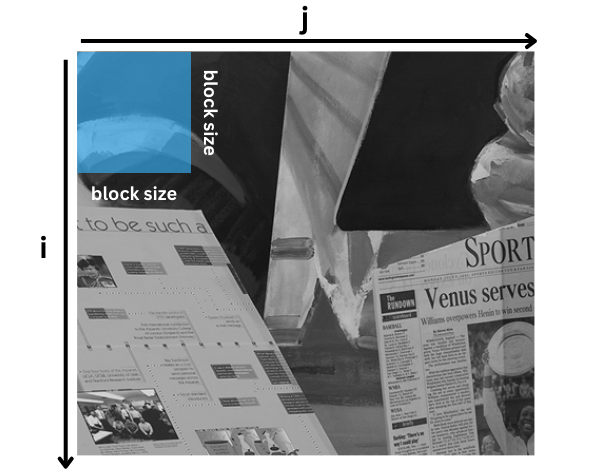

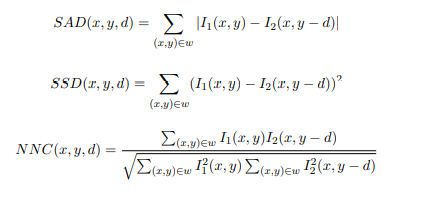

SAD: The SAD algorithm, defined in , considers the absolute difference between the intensity of each pixel in the reference block and that of the corresponding pixel in the target block

SSD: SSD algorithm, in which the summation is performed over the squared differences in pixel intensity values between two corresponding pixels in the aggregated support window 

NNC: The NCC algorithm is another method of determining the correspondence between two windows around a pixel of interest. The normalization within the window compensates for differences in gain and bias

The precision of the algorithm is evaluated based on the Mean Relative Error in the code we used max function to find the  rather then alculating the MRE each time

function [D] = disparityTP1(I1, I2, BlocSize, dispMax, seuilContrast)
if (seuilContrast>1 || seuilContrast<0)
    msg = 'The Threshold should be between 0 and 1'; %just to ensure a valid seuil contrast value
    error(msg)
end
    [h,w] = size(I1);
    D = zeros(h,w);
    BlocSize2 = fix(BlocSize/2);
    for i = 1 + BlocSize2 : h - BlocSize2       % explores rows of the image
        for j = 1 + BlocSize2 : w - BlocSize2   % explores coumns of the image
                       
            % Contrast Check equation (8) or SOBEL kernels (for limiting a block gradient)
            BL1 = I1(i - BlocSize2 : i + BlocSize2, j - BlocSize2 : j + BlocSize2); 
            Cbloc = (max(BL1)-min(BL1))./max(BL1);
            
            if Cbloc <= seuilContrast
                continue
            end
            
            ii = i;
            k = 0;
            for jj = j : min(w - BlocSize2, j + BlocSize2)
                
                % select a block of pixels from Image 2 in the same regrion
                BL2 = I2(ii - BlocSize2 : ii + BlocSize2, jj - BlocSize2 : jj + BlocSize2);
                
                % Compute Similarity here and Store in a vector
                SAD = sum(abs(BL1-BL2));
                SSD = sum((BL1-BL2).^2);
                NNC = sum(sum(BL1.*BL2)/sqrt(sum(sum(BL1.^2))*sum(sum(BL2.^2))));
                
                x(k+1) = max([SAD,SSD,NNC]);
                jj_opt(k+1)=jj;
                k = k+1;
   
            end
            
            % Or: Test the similarity using a metric here
            JJ_opt = find(x, 100);
            J_opt  = jj_opt(JJ_opt);
            BL2    = I2(ii - BlocSize2 : ii + BlocSize2, J_opt - BlocSize2 : J_opt + BlocSize2);
            
            D(i - BlocSize2 : i + BlocSize2, j - BlocSize2 : j + BlocSize2) = abs(BL1-BL2);
      
           [height,width] = size(D) ;
            for indexi=1:height
                for indexj=1:width
                    if D(indexi,indexj)>dispMax
                        D(indexi,indexj) = dispMax;
                    end
                end
            end
          
        end
    end
    

end

#### Extra work 

Python code:

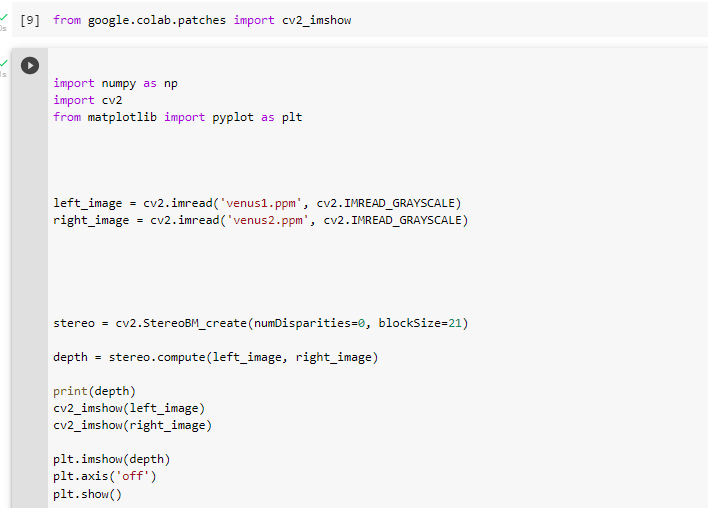

Results: